%% === Setup ===
package_path = fullfile('..', 'ExternalPackages', 'PH-STAT-main');
addpath(package_path);

%% === Subject Lists ===
male_ids = {'100206', '100610', '101309','102109','102513', '102715', '103111', '112112', '130114', '131823'};

male_ids = 1×10 cell 배열
    {'100206'}    {'100610'}    {'101309'}    {'102109'}    {'102513'}    {'102715'}    {'103111'}    {'112112'}    {'130114'}    {'131823'}


female_ids = {'100307', '102311', '102816', '105014', '106521', '107018', '108323', '111009', '111211', '128026'};

female_ids = 1×10 cell 배열
    {'100307'}    {'102311'}    {'102816'}    {'105014'}    {'106521'}    {'107018'}    {'108323'}    {'111009'}    {'111211'}    {'128026'}


all_ids = [male_ids, female_ids];
n_male = length(male_ids);

n_male = 10

n_female = length(female_ids);

n_female = 10

n_total = n_male + n_female;

n_total = 20

data_dir = '../Usedata/rfMRI_ts/';
win_size = 60; % Consistent with the paper 

%% === Function: Load correlation vector and create distance matrix tensor ===
function D_tensor = load_corrvec_to_distance_tensor(file_path, win_size)
    V = readmatrix(file_path); % V is (num_connections, num_time_windows_in_scan)
    n_series = size(V, 2); % Number of time windows in the original scan
    n_points = n_series - win_size + 1; % Number of sliding windows for dynamic embedding
    D_all_windows_cell = cell(1, n_points); % Cell array to store distance matrices for each window

    for t = 1:n_points
        % X: (win_size, num_connections), each row is a brain state (correlation vector)
        X = V(:, t:t+win_size-1)'; 
        % D: (win_size, win_size), Euclidean distance matrix between brain states in the current window
        D = squareform(pdist(X, 'euclidean')); 
        D = double(D);
        D(isnan(D) | isinf(D)) = 999; % Handle NaN/Inf values
        D(1:size(D,1)+1:end) = 0; % Set diagonal to zero
        D = (D + D') / 2; % Ensure symmetry
        D_all_windows_cell{t} = D;
    end
    % D_tensor: (win_size, win_size, n_points), 3D tensor of time-varying distance matrices for one subject
    D_tensor = cat(3, D_all_windows_cell{:}); 
end

%% === Load distance tensors for all subjects ===
% D_all{i} is a (win_size x win_size x n_time_windows_for_dynamic_embedding) tensor for subject i
D_all_subjects = cell(1, n_total); 
for i = 1:n_total
    file = fullfile(data_dir, [all_ids{i}, '_REST1_LR_AAL_corr_vec.txt']);
    D_all_subjects{i} = load_corrvec_to_distance_tensor(file, win_size);
end

%% === Calculate integrated Wasserstein distance between each pair of subjects ===
% subject_pairwise_distances will be an (n_total x n_total) matrix
% where entry (i,j) is L_r(subject_i, subject_j)
subject_pairwise_distances = zeros(n_total, n_total);

% Iterate over each pair of subjects (i, j)
for i = 1:n_total
    for j = i:n_total % Start j from i to avoid redundant calculations and self-comparison for the sum
        
        D_subject_i = D_all_subjects{i}; % Tensor for subject i
        D_subject_j = D_all_subjects{j}; % Tensor for subject j
        
        % Determine the minimum number of time windows for comparison
        % This handles cases where subjects might have slightly different scan lengths after preprocessing
        n_dynamic_windows_min = min(size(D_subject_i, 3), size(D_subject_j, 3));
        
        total_dist_ij = 0; % Integrated distance between subject i and subject j
        
        % Iterate over each time window t of the dynamic embedding
        for t = 1:n_dynamic_windows_min
            D_i_t = D_subject_i(:,:,t); % Distance matrix for subject i at time window t
            D_j_t = D_subject_j(:,:,t); % Distance matrix for subject j at time window t
            
            % --- Calculate Wasserstein distance for the current time window t ---
            % 1. Perform birth-death decomposition for each subject's window matrix
            [Wb_i_t, Wd_i_t] = WS_decompose(D_i_t); % Wb/Wd contain birth/death values in 3rd col
            [Wb_j_t, Wd_j_t] = WS_decompose(D_j_t);
            
            % 2. Calculate squared 2-Wasserstein distance for 0D and 1D homology
            % This corresponds to L_r^b and L_r^d with r=2 (squared)
            % Based on Theorem 2.1, this is sum of squared differences of sorted values [cite: 70]
            dist_0D_t = sqrt(sum((Wb_i_t(:,3) - Wb_j_t(:,3)).^2)); % Squared distance for 0D (births)
            dist_1D_t = sqrt(sum((Wd_i_t(:,3) - Wd_j_t(:,3)).^2)); % Squared distance for 1D (deaths)
            
            % 3. Combine 0D and 1D distances for the current window t
            % This aligns with L_r = sum_t (L_r^b + L_r^d) [cite: 136] (using squared distances here)
            window_dist = dist_0D_t + dist_1D_t; 
            
            % 4. Accumulate the window-wise distance
            total_dist_ij = total_dist_ij + window_dist;
        end
        
        % Store the integrated distance in the symmetric matrix
        subject_pairwise_distances(i,j) = total_dist_ij;
        subject_pairwise_distances(j,i) = total_dist_ij; 
    end
end

%% === Compute Ratio Statistic ===
% Use the subject_pairwise_distances matrix as the loss matrix
observed_ratio = WS_ratio(subject_pairwise_distances, n_male, n_female);
fprintf("Observed ratio statistic (subject-level): %.4f\n", observed_ratio);

Observed ratio statistic (subject-level): 1.1610



%% === Perform Transposition Test ===
n_trans = 10000; % Number of transpositions, paper used 50 million [cite: 211]
perm_no = 1000;  % Intermix with a full permutation every 'perm_no' transpositions, same as paper [cite: 211]
[transStat, ~] = WS_transpositions(subject_pairwise_distances, n_male, n_female, n_trans, perm_no);

%% === Compute p-value ===
% Proportion of permuted stats greater than or equal to the observed stat [cite: 158]
p_value = sum(transStat >= observed_ratio) / n_trans;
fprintf("Transposition test p-value (subject-level): %.4f\n", p_value);

Transposition test p-value (subject-level): 0.0401


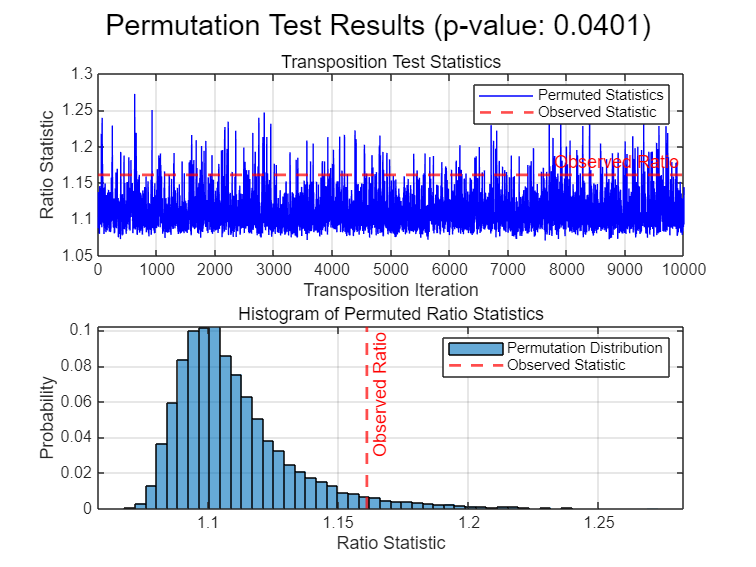

%% === Visualize Results ===
figure;

subplot(2,1,1);
plot(transStat, 'b');
hold on;
yline(observed_ratio, 'r--', 'LineWidth', 1.5, 'Label', 'Observed Ratio');
xlabel('Transposition Iteration');
ylabel('Ratio Statistic');
title('Transposition Test Statistics');
legend('Permuted Statistics', 'Observed Statistic');
grid on;

subplot(2,1,2);
histogram(transStat, 50, 'Normalization', 'probability');
hold on;
xline(observed_ratio, 'r--', 'LineWidth', 1.5, 'Label', 'Observed Ratio');
xlabel('Ratio Statistic');
ylabel('Probability');
title('Histogram of Permuted Ratio Statistics');
legend('Permutation Distribution', 'Observed Statistic');
grid on;

sgtitle(sprintf('Permutation Test Results (p-value: %.4f)', p_value), 'FontSize', 16);